ceid = '171104_AD6';  % change this

path_ang = ['D:\kwalek\' ceid '\rbc_angio.mat'];
path_RRR = ['D:\kwalek\' ceid '\RRR.mat'];
path_save = ['D:\kwalek\' ceid ];
load(path_ang)
load(path_RRR)


## load


load('net_unet.mat')
load('net_reg'); %regression (EnhVess)
load('net12_16_final.mat'); %segmentation (SegVess)
load('corrnet_3layers.mat')
load('inception_real_uncertainty.mat')


% DD2 = DD;
% DD = medfilt3(DD,[3 3 3]);
% DD = imresize3(mat2gray(log(DD)), [size(DD,1) size(DD,2)*2 size(DD,3)*2]);
%above block is old, below is my new
DD = imresize3(DD, [size(DD, 1) 2*size(DD, 2) 2*size(DD, 3)], 'linear');
DD(DD == 0) = mean(DD(DD(:)~=0));
DD = medfilt3(DD);


logDD = log(DD); %used to be just logDD = DD
logDD = mat2gray(logDD);

[s1, s2, s3] = size(logDD);
m1 = mod([s1 s2 s3],32);
p1 = 0; p2 = 0; p3 = 0;

if m1(1) > 0
    p1 = 32-m1(1);
end

if m1(2) > 0
    p2 = 32-m1(2);
end

if m1(3) > 0
    p3 = 32-m1(3);
end

if sum(m1) > 0
    logDD = padarray(logDD, [p1 p2 p3], 'post');
end

Enh = activations(net_reg, logDD, 'regressionoutput', 'executionenvironment', 'cpu');
Enh = Enh(1:s1,1:s2,1:s3);
Enh2 = activations(net, logDD, 'reg', 'executionenvironment', 'cpu');
Enh2 = Enh2(1:s1,1:s2,1:s3);
logDD = logDD(1:s1,1:s2,1:s3);
Enh = max(Enh,Enh2);

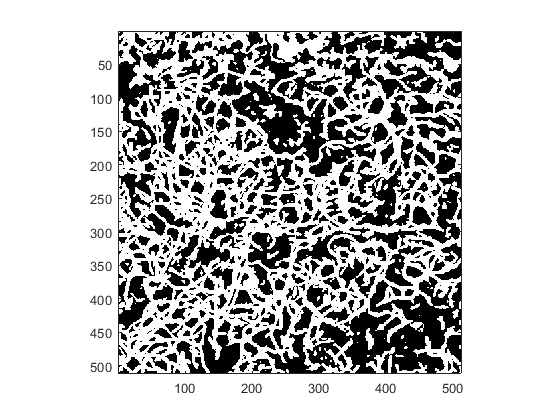

[s1, s2, s3] = size(Enh);
m1(1) = mod(s1,12);
m1(2) = mod(s2,16);
m1(3) = mod(s3,16);
p1 = 0; p2 = 0; p3 = 0;

if m1(1) > 0
    p1 = 12-m1(1);
end

if m1(2) > 0
    p2 = 16-m1(2);
end

if m1(3) > 0
    p3 = 16-m1(3);
end

if sum(m1) > 0
    Enh = padarray(Enh, [p1 p2 p3], 'post');
end

seg_approx = semanticseg(Enh,net12_16_final, 'executionenvironment', 'cpu');
seg_approx = double(seg_approx) - 1;
seg = imclose(seg_approx,ones(3,3,3));

seg = seg(1:s1,1:s2,1:s3);
Enh = Enh(1:s1,1:s2,1:s3);


seg = imgaussfilt3(seg,1) > 0.3;

mip = squeeze(max(seg,[],1));
figure; imagesc(squeeze((mip)))
colormap(gray)
axis image

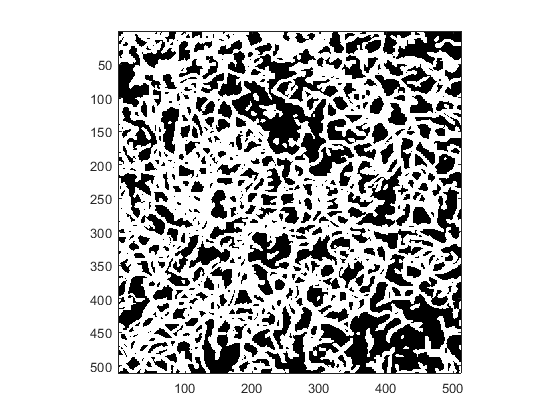

clear c;
c(:,:,:,1) = mat2gray(logDD);
c(:,:,:,2) = Enh;
c(:,:,:,3) = seg;
seg_corr = activations(corrnet,c,'dice', 'executionenvironment','cpu');
seg2 = max(seg_corr(1:s1,1:s2,1:s3,2),seg);
seg2 = seg2>0.3;
seg2 = imclose(seg2,ones(3,3,3));


%remove any small unconnected components
CC  = bwconncomp(seg2);
numPixels = cellfun(@numel,CC.PixelIdxList);
ind = find(numPixels > 30);
res = zeros(size(seg2));
for i = 1:length(ind)
    res(CC.PixelIdxList{ind(i)}) = 1;
end

mip = squeeze(max(res,[],1));
figure; imagesc(squeeze((mip)))
colormap(gray)
axis image

skel = bwskel(res>0);
skel = imdilate(skel, strel('sphere',2));
skel = imresize3(double(skel), [size(skel,1), size(skel,2)/2, size(skel,3)/2]);
skel = imgaussfilt3(skel,1)>0.3;
skel = bwskel(skel>0);
S = rem_small(skel);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 12).


clear Sn
M = DD2.*imdilate(skel, strel('sphere',2));
for j = 1:length(S)
    s = S{j};
    sing_sk = zeros(size(skel));
    for i = 1:size(s,1)
        sing_sk(s(i,1), s(i,2), s(i,3)) = 1;
    end
    %sk2 = recenter_std(sing_sk,OO_std);
    sk2 = recenter(sing_sk,M);
    if sum(sk2(:))>2
        try
            se = segm3(sk2);
            Sn{j} = se{1};
        catch
            Sn{j} = S{j};
        end
    else
        Sn{j} = S{j};
    end
    if mod(j,100) == 0
        disp([num2str(j) '/' num2str(length(S)) ' completed'])
    end
    
end

100/1653 completed
200/1653 completed
300/1653 completed
400/1653 completed
500/1653 completed
600/1653 completed
700/1653 completed
800/1653 completed
900/1653 completed
1000/1653 completed
1100/1653 completed
1200/1653 completed
1300/1653 completed
1400/1653 completed
1500/1653 completed
1600/1653 completed


%%

cs = cellfun(@(x) size(x,1), S);
csn = cellfun(@(x) size(x,1), Sn);

Sn(csn<0.9*cs) = S(csn<0.9*cs);

clear S_fl S_std

% I1 = abs(rm0).^2; %try this

for i = 1:length(Sn)
    s = Sn{i};
    S2 = zeros(512,size(s,1));
    for j = 1:size(s,1)
        xy = squeeze(rm0(s(j,1), s(j,2), s(j,3),:)); %this was commented
%         xy = squeeze(I1(s(j,1), s(j,2), s(j,3),:));
        xy = highpass(xy, 10,714); %
        xy = xy - median(xy); %
        S2(:,j) = mat2gray(imgaussfilt(abs(xy).^2,1)); %
%         S2(:,j) = mat2gray(xy);
    end
    oo = activations(net_flux, reshape(S2, 512,1,1,size(S2,2)), 'regressionoutput');
    oo = squeeze(oo);
    S_fl{i} = oo(1,:);
    S_std{i} = oo(2,:);
    if mod(i,100) == 0
        disp([num2str(i) '/' num2str(length(Sn))])
    end
end

Index in position 1 exceeds array bounds (must not exceed 41).


%R2_value_Diameter;
F = zeros(1,length(Sn));
for i = 1:length(Sn)
    fl = S_fl{i}; v= S_std{i};
   % fl = fl(R{i}>0.95); v = v(R{i}>0.95);
    if isempty(fl) == 0  
    f = fl(v==min(v));
    F(i) = f(1);
    else
        F(i) = nan;
    end
end


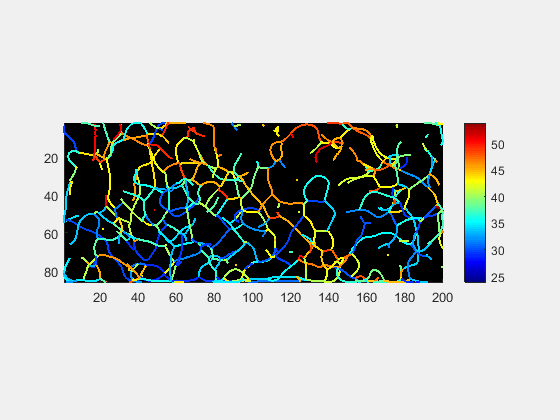

F = round(F);
fl_uniq = 1:max(F);%unique(F);
c = jet(length(fl_uniq));

figure('visible', 'on'); 

hold on
for i = 1:length(S)
    if ~isnan(F(i)) 
    ind = find(F(i) == fl_uniq);
    plot(smooth(S{i}(:,3)), smooth(S{i}(:,2)), 'linewidth', 1.5, 'color', c(ind,:))
    end
end

axis image
set(gca,'Color','k')
set(gcf, 'InvertHardCopy', 'off');
ax = gca;
ax.YDir = 'reverse';
colormap(c);
caxis([nanmean(F)-nanstd(F) nanmean(F)+nanstd(F)])
colorbar

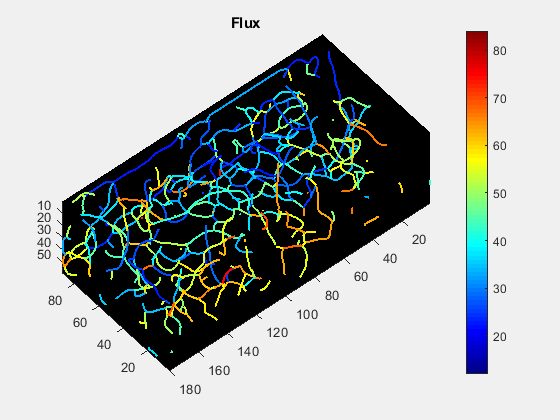

c = jet(length(fl_uniq));
figure('visible', 'on'); hold on; 
for i = 1:length(S)
    if ~isnan(F(i))
        ind = find(F(i) == fl_uniq);
        plot3(smooth(S{i}(:,3)), smooth(S{i}(:,2)), smooth(S{i}(:,1)),'linewidth', 1.5, 'color', c(ind,:))
    end
end
ax = gca;
ax.YDir = 'reverse';
ax.ZDir = 'reverse';
axis image
view(140,50)
colormap(c);
caxis([min(F) max(F)])
colorbar
set(gca,'Color','k')
set(gcf, 'InvertHardCopy', 'off');
title('Flux')

clear rm0
save([path_save '\rbc_flux'])